# Jmag Express

filename=


jexpress = actxserver(strcat('express.Application.','140'));   
jexpress.CreateNewCombination('PM_I_D_I','rip_013','so_001')

deGeo=jexpress.GetParameterListXML()


jexpress.SetProperty('SLOTS@stator@parts',72)
% jexpress.SetProperty('SLOTS@stator@parts',36)

jexpress.SetProperty('SD1@stator@parts',i_Stator_OD)
jexpress.SetProperty('SD2@stator@parts',(i_Stator_OD *i_Split_Ratio))
jexpress.SetProperty('SW1@stator @parts',36)
jexpress.SetProperty('SW2@stator @parts',36)
jexpress.SetProperty('SW4@stator @parts',36)
jexpress.SetProperty('ST@stator  @parts',36)
jexpress.SetProperty('STD1@stator@parts',36)
jexpress.SetProperty('SF1@stator @parts',36)

## Rotor

jexpress.SetProperty("RD1@ipm_rotor@parts",            (i_Stator_OD *i_Split_Ratio)-hag*2            )  
jexpress.SetProperty("RD2@ipm_rotor@parts",            Rshaft*2            )  
jexpress.SetProperty("MW1@ipm_rotor@parts",                        )  
jexpress.SetProperty("MT1@ipm_rotor@parts",                        )  
jexpress.SetProperty("DMAG1@ipm_rotor@parts",                        )
jexpress.SetProperty("MW2@ipm_rotor@parts",                        )  
jexpress.SetProperty("MT2@ipm_rotor@parts",                        )  
jexpress.SetProperty("DMAG2@ipm_rotor@parts",                        )

## 3D

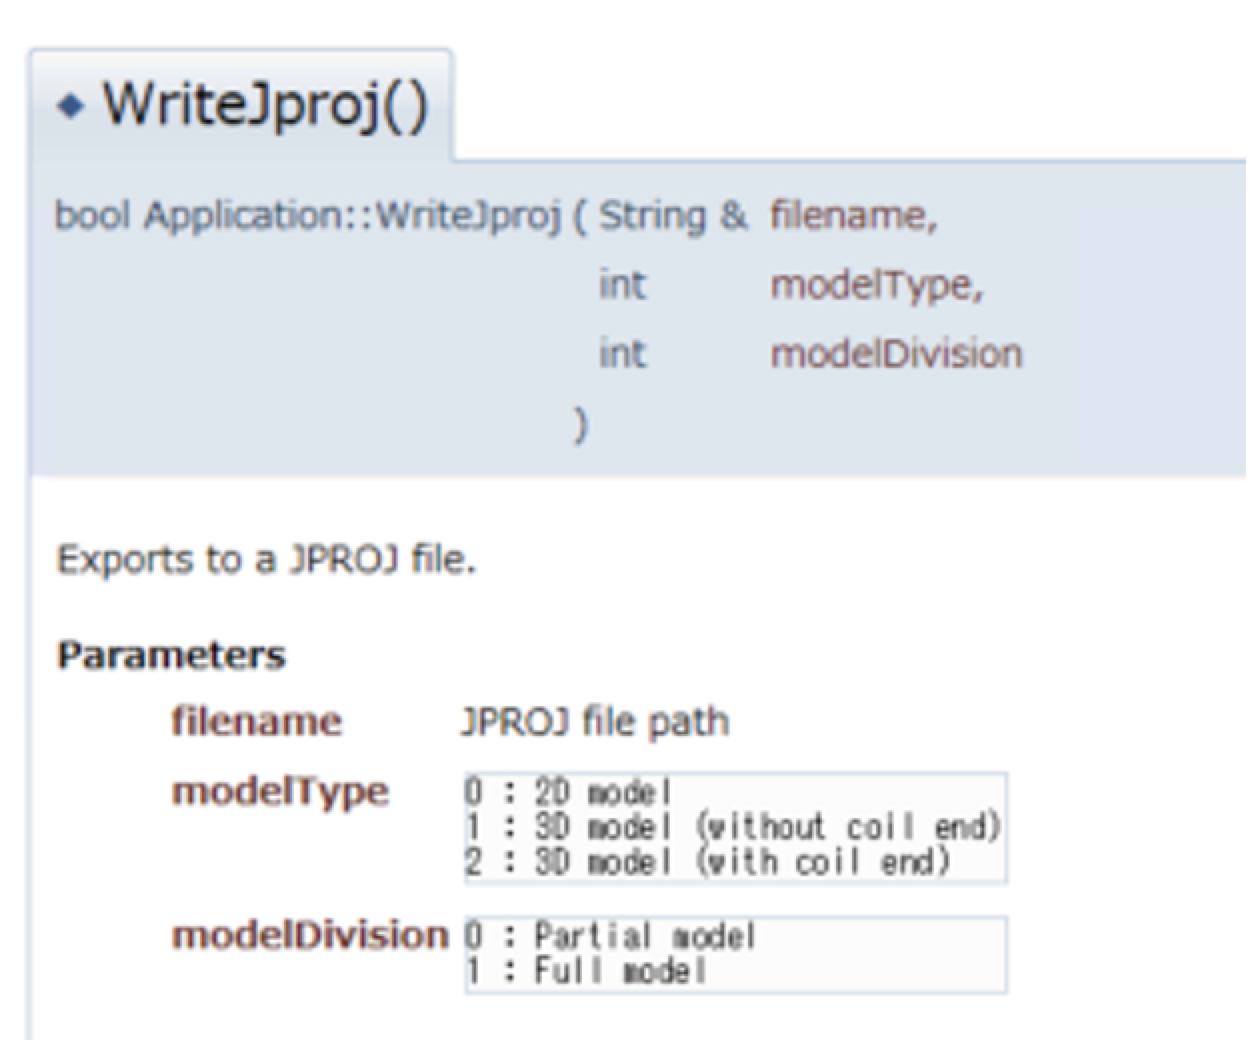

jexpress.WriteJproj(filename,2,0)